% ratio = zeros(1,length(results));
% for i=1:length(results)
%     ec_cur = results(i).SCnew;
%     ec_cur(ec_cur>0) = 0;
%     ec_cur(ec_cur~=0) = 1;
%     fcemp = FCemp1;
%     fcemp(fcemp>0) = 0;
%     fcemp(fcemp~=0) = 1;
%     mask = fcemp.*ec_cur;
%     ratio(i) = sum(mask~=0,'all')/(sum(ec_cur~=0,'all'));
% end
% figure('Color',[1 1 1]);
% plot(1:length(ratio),ratio,'Color',[95 151 210]/255,'LineStyle','-','LineWidth',1.5);
% grid on;
% title('overlapped edges / negative edges of EC')

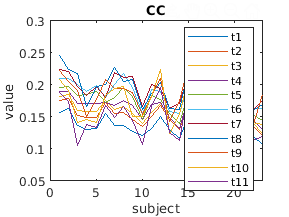

figure('Color',[1 1 1]);
plot(emphc_net(:,:,1)');
xlabel('subject');
ylabel('value')
ylim([0.05,0.3])
legend('t1','t2','t3','t4','t5','t6','t7','t8','t9','t10','t11')
title('CC')

% clear all
% close all
% load emp_sim_iter8_net_Eloc.mat
% max_lim = max(max([simad_net;empmad_net]));
% min_lim = min(min([simad_net;empmad_net]));
% figure('color',[1 1 1]);
% subplot(2,1,1);
% imagesc(empmad_net);colorbar;colormap('hot');caxis([min_lim,max_lim]);title('Eloc-ad-emp-net')
% xlabel('brain areas')
% ylabel('threshold')
% subplot(2,1,2);
% imagesc(simad_net);colorbar;colormap('hot');caxis([min_lim,max_lim]);title('Eloc-ad-sim-net')
% xlabel('brain areas')
% ylabel('threshold')
% clear all
% load emp_sim_iter8_net_C.mat
% max_lim = max(max([simad_net;empmad_net]));
% min_lim = min(min([simad_net;empmad_net]));
% figure('color',[1 1 1]);
% subplot(2,1,1);
% imagesc(empmad_net);colorbar;colormap('hot');caxis([min_lim,max_lim]);title('CC-ad-emp-net')
% xlabel('brain areas')
% ylabel('threshold')
% subplot(2,1,2);
% imagesc(simad_net);colorbar;colormap('hot');caxis([min_lim,max_lim]);title('CC-ad-sim-net')
% xlabel('brain areas')
% ylabel('threshold')

% figure('Color',[1 1 1]);
% plot(1:1000,corr_hc);
% hold on
% plot(1:1000,corr_mci);
% hold on
% plot(1:1000,corr_ad);
% xlabel('number of iterations')
% ylabel('corr');
% legend('HC','MCI','AD')